# MOST Calculation

Reference: Stull's textbook "An Introduction to Boundary Layer Meteorology"

Goal - solve for aerodynamic roughness from a logarithmic velocity profile model

## Step 1

#### Load data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\MOSTaeroRoughness'
cd data\input\
load('BFLAT_edcov.mat')
BFLAT_edcov(1:85,:) = []; %poor early data.

## Step 2

#### filter data

#### L > 100 m (100 is an approximation, bigger is better)

% histogram(BFLAT_edcov.("3m L:sqrt(uPF'wPF')^3/2*T_S/(k*g*wPF'Ts')"))
BFLAT_edcov.Lfiltered = (BFLAT_edcov.("3m L:sqrt(uPF'wPF')^3/2*T_S/(k*g*wPF'Ts')") > 100).*BFLAT_edcov.("3m L:sqrt(uPF'wPF')^3/2*T_S/(k*g*wPF'Ts')");
BFLAT_edcov.Lfiltered(BFLAT_edcov.Lfiltered ==0) = NaN;

### Deleting poor L

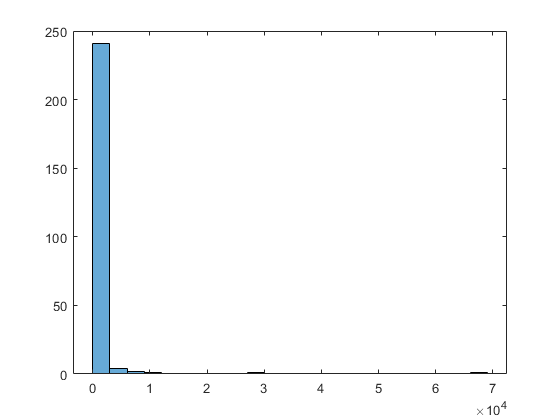

BFLAT_edcov = sortrows(BFLAT_edcov,'Lfiltered','ascend');
BFLAT_edcov(251:end,:) = [];

figure
histogram(BFLAT_edcov.Lfiltered)

#### Filter wind speed (W) is 2 < W < 6 m/s

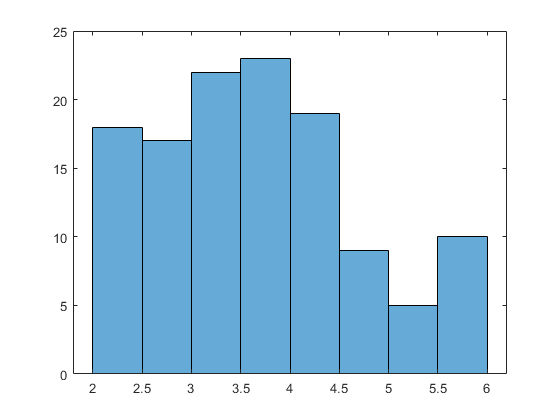

% histogram(BFLAT_edcov.("3m speed"))
BFLAT_edcov.wind_ms = (BFLAT_edcov.("3m speed") < 6).*(BFLAT_edcov.("3m speed"));
% histogram(BFLAT_edcov.wind_ms)
BFLAT_edcov.wind_ms = (BFLAT_edcov.wind_ms > 2).*BFLAT_edcov.wind_ms;
BFLAT_edcov.wind_ms(BFLAT_edcov.wind_ms ==0) = NaN;
histogram(BFLAT_edcov.wind_ms)

### Deleting windspeed outside of range

BFLAT_edcov = sortrows(BFLAT_edcov,'wind_ms','ascend');
BFLAT_edcov(124:end,:) = [];

## Step 3 - Solve for Zo (aerodynamic roughness)

#### Constants

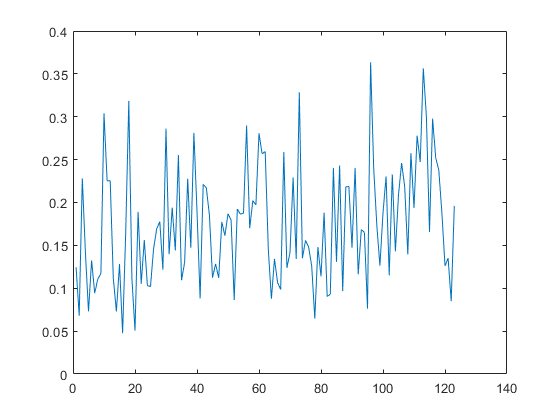

mbar = BFLAT_edcov.wind_ms; % windspeed (m/s)
ustar = BFLAT_edcov.ustar; %friction velocity (m/s) (typically between 0 and 2)
% ustar = BFLAT_edcov.ustarWPF; %friction velocity (m/s) (typically between 0 and 2)

% histogram(ustar)
plot(ustar)

K = 0.4 % von Karman Constant

K = 0.4000

Z = 2.565 %sonic measurement height (m)

Z = 2.5650

% Znaught = aerodynnamic roughness
% Psim = Stability Function (eqn's 9.7.5h and 9.7.5i in Stull). 
L = BFLAT_edcov.Lfiltered; %monin-obukhov length scale

% Rearrange eqn 9.7.5g (Stull) solve for Znaught, select period with 1/L is small,
% then can neglect Psim, leaving

Znaught = Z./(exp(K*mbar./ustar));
% Note - only use data with windspeed between 2-6 m. 

## Step 4

#### Process data for aerodynamic roughness, data will vary widely, use the median value

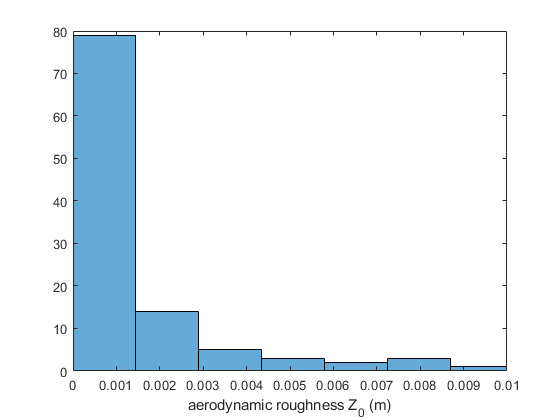

%Plot this as a histogram, and select median from it. 
histogram(Znaught,100)
% plot(Znaught)
xlabel('aerodynamic roughness Z_0 (m)')
xlim([0,0.01])

median(Znaught) %aerodynamic roughness

ans = 5.3692e-04